clc;
clear all;
close all;
%% 数据处理
% 初始化一个空矩阵用于存储所有数据
allData = [];

% 文件名列表
fileNames = {'simout_false_1.mat', 'simout_false_2.mat', 'simout_false_3.mat', 'simout_false_4.mat', 'simout_false_5.mat'};

% 遍历文件名列表并加载数据
for i = 1:length(fileNames)
    % 获取文件名和变量名中的序号
    fileName = fileNames{i};
    underscoreIndex = strfind(fileName, '_');
    dotIndex = strfind(fileName, '.');
    fileNumber = fileName(underscoreIndex(end)+1:dotIndex-1);
    variableName = ['simout_', fileNumber];
    
    % 加载文件
    data = load(fileName);
    
    % 检查是否存在对应的变量
    if isfield(data, variableName)
        simout = data.(variableName);
        
        % 将当前文件的数据添加到 allData 矩阵
        allData = [allData; simout];
    else
        error(['数据中没有找到变量 ', variableName, ': ', fileName]);
    end
end

% 确认所有数据已成功加载
disp('所有数据已成功加载并整合');

% 假设第42列为label
labels = allData(:, 42);
features = allData(:, 1:41);

% 获取数据的行数
numRows = size(allData, 1);

% 随机排列行
randomOrder = randperm(numRows);
features = features(randomOrder, :);
labels = labels(randomOrder);

% 计算训练集和测试集的大小
numTrain = round(0.7 * numRows);
numTest = numRows - numTrain;

% 划分训练集和测试集
X_train = features(1:numTrain, :);
Y_train = labels(1:numTrain);
X_test = features(numTrain+1:end, :);
Y_test = labels(numTrain+1:end);

% 保存训练集和测试集到一个新的 .mat 文件中
save('combined_data.mat', 'X_train', 'Y_train', 'X_test', 'Y_test');

disp('数据集已成功划分并保存');


%% 网络训练
% 加载数据
load('combined_data.mat', 'X_train', 'Y_train', 'X_test', 'Y_test');

hiddenLayerSize = 10; % 隐含层大小
net = patternnet(hiddenLayerSize); % 创建网络

% 训练参数
net.trainFcn = 'trainscg';  % 使用 Scaled conjugate gradient backpropagation
% net.trainFcn = 'trainlm';   % 使用 Levenberg-Marquardt backpropagation
% net.trainFcn = 'trainbfg';    % 使用 BFGS quasi-Newton backpropagation
net.trainParam.epochs = 500;     % 设置最大训练次数
net.trainParam.goal = 1e-3;      % 设置目标误差
net.trainParam.lr = 0.01;        % 设置学习速率

% 标签转换
Y_train_onehot = full(ind2vec(Y_train'));
Y_test_onehot = full(ind2vec(Y_test'));

% 训练网络
[net, tr] = train(net, X_train', Y_train_onehot);

% 预测
Y_pred_onehot = net(X_test');
Y_pred = vec2ind(Y_pred_onehot);

% 计算准确率
accuracy = sum(Y_pred' == Y_test) / length(Y_test);
fprintf('Test Accuracy: %.2f%%\n', accuracy * 100);

Test Accuracy: 98.63%


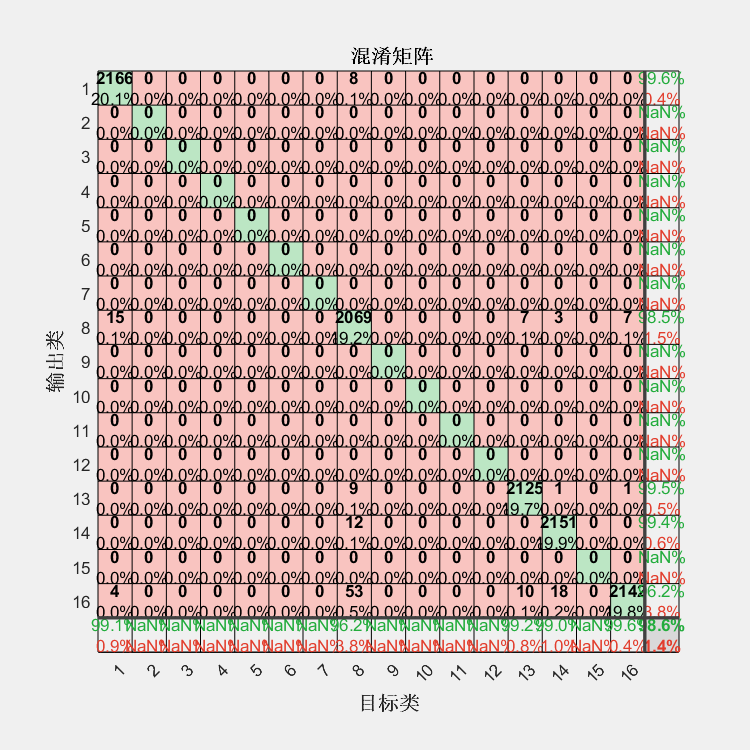


% 混淆矩阵
figure;
plotconfusion(Y_test_onehot, Y_pred_onehot);

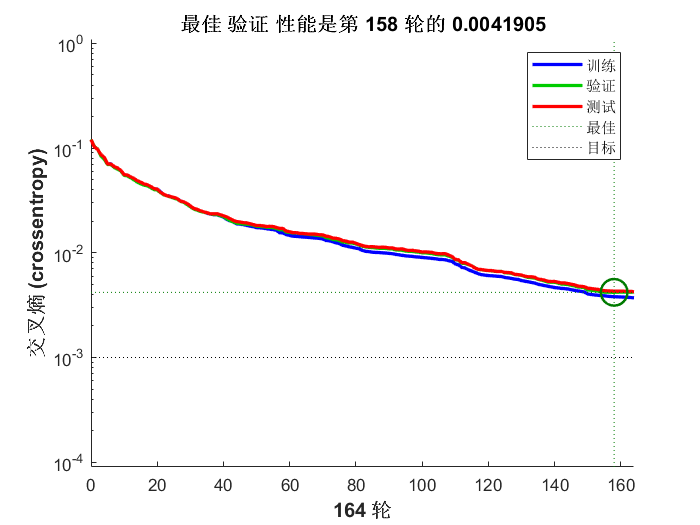


% 训练过程
figure;
plotperform(tr);


% 保存网络
% save('trained_BP_neural_network.mat', 'net', 'tr');
